**4.** **Harris Corner Detection**

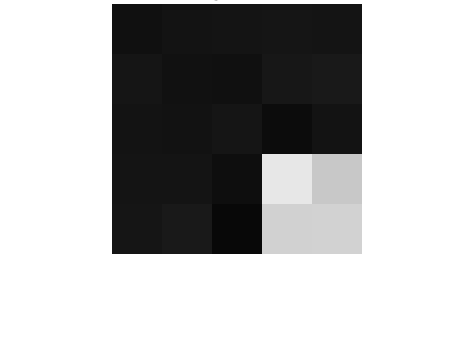

% Read the 5x5 image patch
img = imread('./corner2.jpg');

% Magnify the image and then display because of the small size
imshow(img, InitialMagnification=5000);
title('image patch');

% Apply Harris Corner Detection algorithm using a 3x3 filter
corners = detectHarrisFeatures(img,"FilterSize",3)

corners =   cornerPoints with properties:

    Location: [3.8394 4.0435]
      Metric: 0.0672
       Count: 1


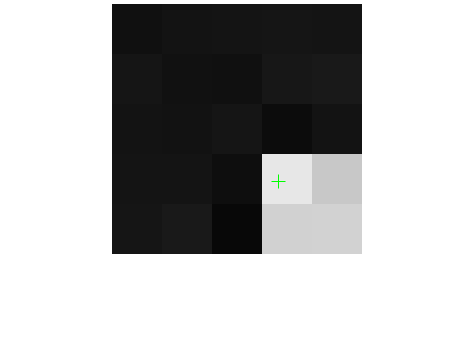

% Sicne only 1 corner is found, display the strongest corner
figure;
imshow(img, InitialMagnification=5000); title('Detected Corner');

hold on;
plot(corners.selectStrongest(10));

As we can see, the detected corner is marker by a green cross.